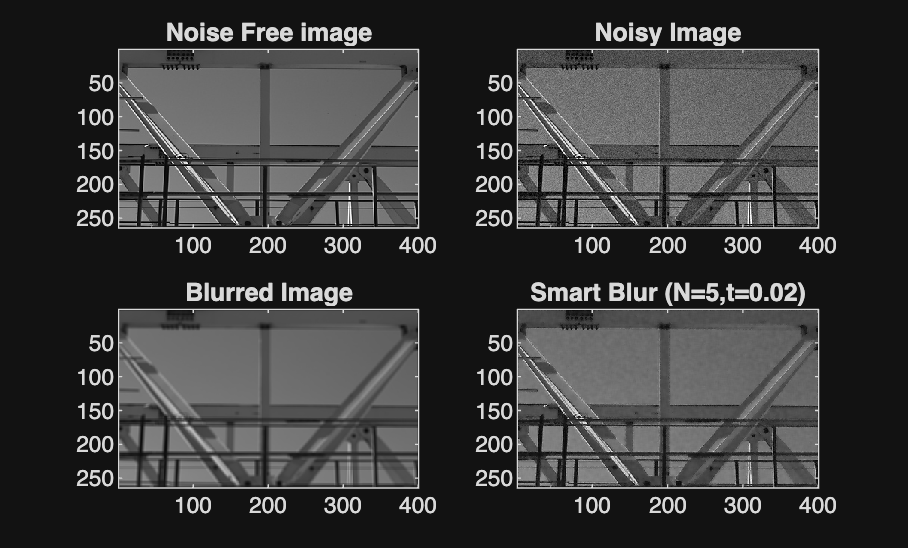

% test image
I = imread('gantrycrane.png');
%I =imread('pout.tif');
%I = imread('peppers.png');

% force into single channel, greyscale 0..1
if (size(I,3)==3)
  I=rgb2gray(I);
end
I = im2double(I);

% add noise
Inoisy = imnoise(I,'gaussian',0,0.002);

N=5;

% start plotting
figure(99);
subplot(2,2,1);
imagesc(I); cax=caxis;
title('Noise Free image');
subplot(2,2,2);
imagesc(Inoisy); caxis(cax);
title('Noisy Image');
B = conv2(I,ones(N,N)/(N*N),'same');
subplot(2,2,3);
imagesc(B); caxis(cax);
title('Blurred Image');

% run smart blur
Ismart = smart_blur(Inoisy,N,0.02);

% finish plotting
figure(99);
subplot(2,2,4);
imagesc(Ismart); caxis(cax);

title('Smart Blur (N=5,t=0.02)');

colormap(gray(256));

drawnow

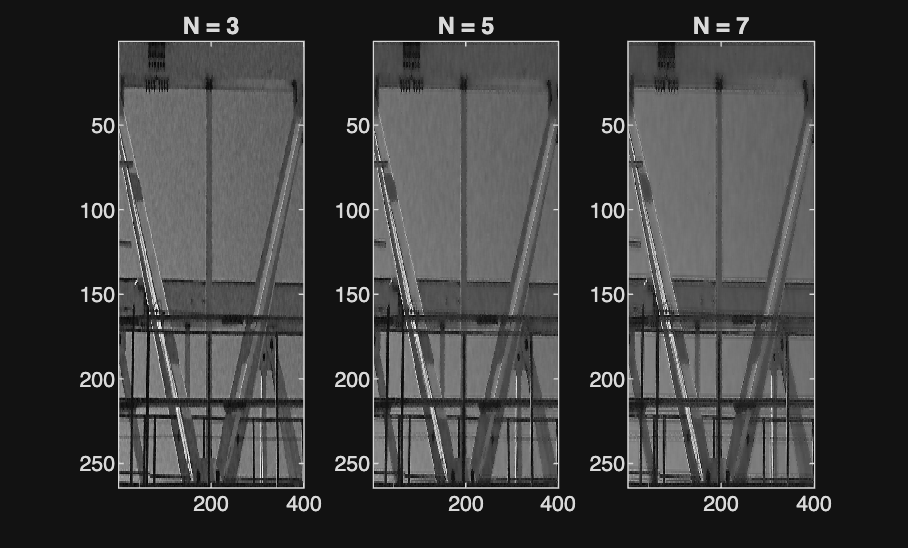

% smart blur experiments
% changing N, t stays at the default 0.02
S3 = smart_blur(Inoisy, 3, 0.02);
S5 = smart_blur(Inoisy, 5, 0.02);
S7 = smart_blur(Inoisy, 7, 0.02);

figure
subplot(1,3,1); imagesc(S3); caxis(cax); title('N = 3');
subplot(1,3,2); imagesc(S5); caxis(cax); title('N = 5');
subplot(1,3,3); imagesc(S7); caxis(cax); title('N = 7');
colormap(gray(256));

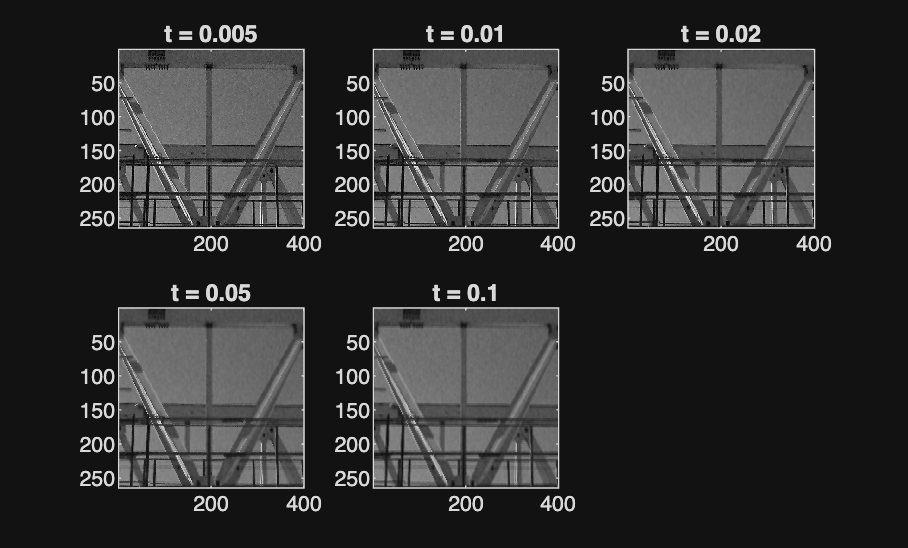

% smart blur experiments
% changing t, N stays at the default 5
T1 = smart_blur(Inoisy, 5, 0.005);
T2 = smart_blur(Inoisy, 5, 0.01);
T3 = smart_blur(Inoisy, 5, 0.02);
T4 = smart_blur(Inoisy, 5, 0.05);
T5 = smart_blur(Inoisy, 5, 0.1);

figure
subplot(2,3,1); imagesc(T1); caxis(cax); title('t = 0.005');
subplot(2,3,2); imagesc(T2); caxis(cax); title('t = 0.01');
subplot(2,3,3); imagesc(T3); caxis(cax); title('t = 0.02');
subplot(2,3,4); imagesc(T4); caxis(cax); title('t = 0.05');
subplot(2,3,5); imagesc(T5); caxis(cax); title('t = 0.1');
colormap(gray(256));